# Analyzing the Labeled Data

## Loading the Ground Truth

Loading the ground truth and creating the image and box label datastores.

load parkingTrainGT.mat gTruth
gTruth

gTruth =   groundTruth with properties:

          DataSource: [1×1 groundTruthDataSource]
    LabelDefinitions: [3×5 table]
           LabelData: [400×3 table]


The function below creates an image and box label datastore for object detection.

[imds, blds] = objectDetectorTrainingData(gTruth);

### Viewing summary of object labels and the LabelData

countEachLabel(blds)

ans = 3×3 table
      Label       Count    ImageCount
    __________    _____    __________

    Accessible     167        144    
    Charger        106        106    
    EV             223        201    


## **Creating a Table for Analyzing Bounding Boxes**

The `createBoundingBoxTable` is a helper function located at the bottom of the script that reorganizes the data into a table for analysis and visualization.

bboxes = createBoundingBoxTable(blds)

bboxes = 496×3 table
    ImgIdx              BBox                Label   
    ______    ________________________    __________

       1      198     99     84    121    EV        
       2      215    137     47     47    Accessible
       3      210    131     60     60    Accessible
       4      218    139     39     44    Accessible
       5      194    106     89    122    EV        
       6       21     86    129    159    EV        
       7      112     65    160    187    EV        
       8      200     86    107    153    EV        
       9      199     96     88    121    EV        
      10      214    134     48     47    Accessible
      11      197     95     98    139    EV        
      12      207     92     71    136    EV        
      13       17    140     43     84    EV        
      13      210    108     60    105    EV        
      14      181     89    

### Adding area and aspect ratio

The bounding box coordinates for each object is a 1x4 vector. The first two elements are the x and y locations of the upper left corner of the box. The third and fourth elements are the width and height of the bounding box. The code below uses the width and height to calculate the area and aspect ratio of the boxes and adds these quantities to the table.

bboxes.Area = bboxes.BBox(:,3) .* bboxes.BBox(:,4);
bboxes.AspectRatio = bboxes.BBox(:,3) ./ bboxes.BBox(:,4);
bboxes

bboxes = 496×5 table
    ImgIdx              BBox                Label       Area     AspectRatio
    ______    ________________________    __________    _____    ___________

       1      198     99     84    121    EV            10164      0.69421  
       2      215    137     47     47    Accessible     2209            1  
       3      210    131     60     60    Accessible     3600            1  
       4      218    139     39     44    Accessible     1716      0.88636  
       5      194    106     89    122    EV            10858      0.72951  
       6       21     86    129    159    EV            20511      0.81132  
       7      112     65    160    187    EV            29920      0.85561  
       8      200     86    107    153    EV            16371      0.69935  
       9      199     96     88    121

## Creating Visualizations and Analyzing Bounding Boxes

### Creating a scatter plot

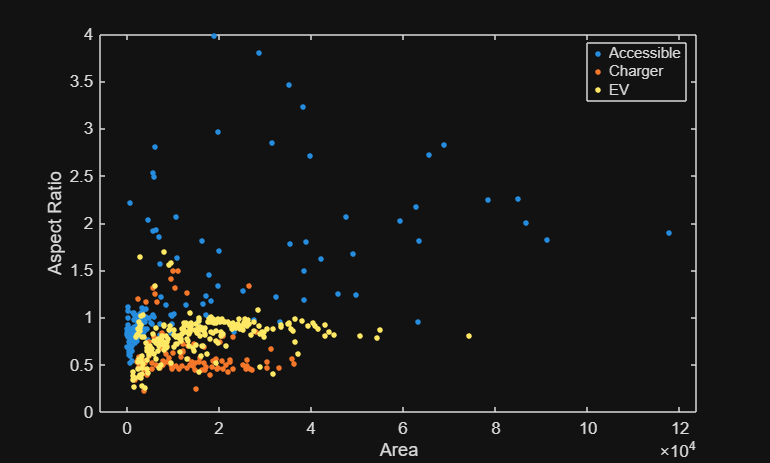

gscatter(bboxes.Area, bboxes.AspectRatio, bboxes.Label)
xlabel("Area")
ylabel("Aspect Ratio")

### Creating box plots of aspect ratios for each class

Here, the distribution of the aspect ratios for each class is shown. 

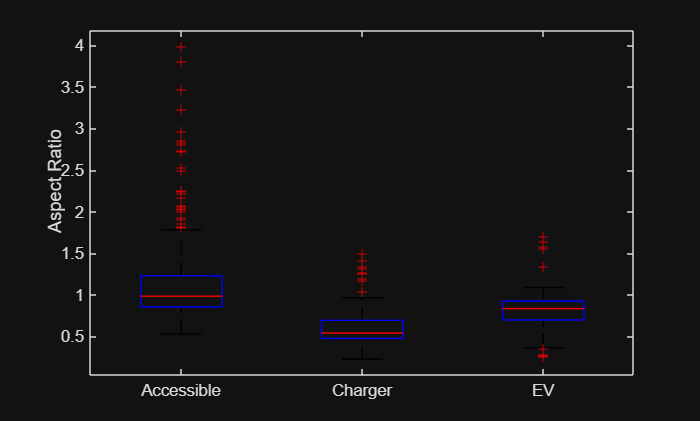

boxplot(bboxes.AspectRatio, bboxes.Label)
ylabel("Aspect Ratio")

### Creating a box plot of area for each class

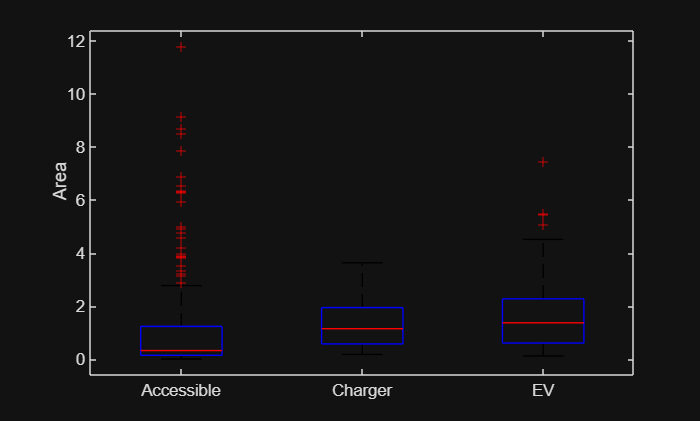

boxplot(bboxes.Area, bboxes.Label)
ylabel("Area")

## Investigating Selected Outliers

Use the drop-down menus below to find the outliers for a specific class and variable. `displayOutlierImage `is a helper function at the bottom of the script that uses your selections to display the outlier object or message to help you set the controls. 

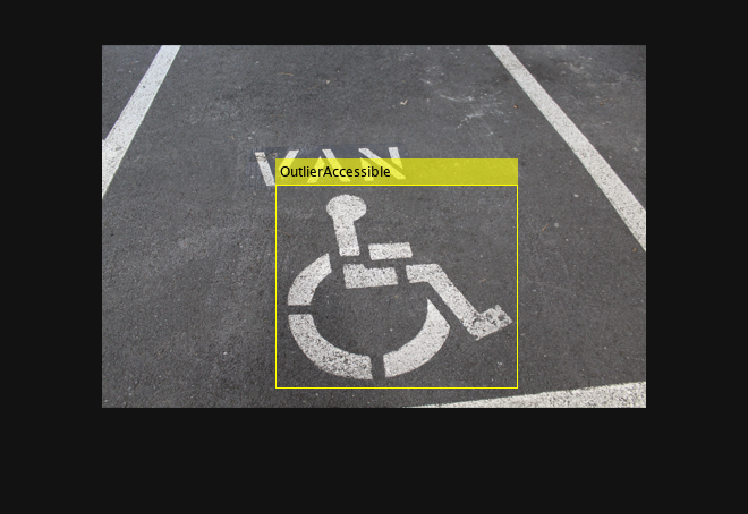

class = "Accessible";
variable = "Area";
outlier2view = 1;
displayOutlierImage(bboxes, class, variable, outlier2view, imds);

## Helper Functions

function bboxes = createBoundingBoxTable(blds)
% This helper function extracts the LabelData from a box label datastore and
% creates a table with one row for each object instead of one row for each
% image.

    % Extracting the label data
    data = blds.LabelData;

    % Initializing variables to include in the table
    % ImgIdx is the index of the image in the image datastore
    % BBox is a 1x4 vector with the bounding box coordinates
    % Label is the label for the bounding box
    ImgIdx = [];
    BBox = [];
    Label = [];

    % Looping through each row in the cell array and get the bounding boxes 
    % and labels for that image.
    for ii = 1:height(data)
        currentBoxes = data{ii,1};
        currentLabels = data{ii,2};
        % Looping through the objects in the image 
        % Adding the image, bounding box, and label to the corresponding variable
        for jj = 1:height(currentLabels)
            ImgIdx = [ImgIdx; ii];
            BBox = [BBox; currentBoxes(jj,:)];
            Label = [Label; currentLabels(jj)];
            
        end
    end
    % Creating the output table
    bboxes = table(ImgIdx, BBox, Label);
end

function displayOutlierImage(bboxes, class, variable, outlier2view, imds)
% This help function uses the selections set by live controls to find and
% display outlier images. If the numeric selection is higher than the
% number of outliers, a message is displayed.

    % Filtering the bounding boxes by class
    classTable = bboxes(bboxes.Label == class, :);
    
    % Finding outlier bounding boxes based on the specified variable using quartiles
    % quartiles is used as the default for box plots and is better when
    % there are objects in the same class with different sizes.
    outlierBBoxes = find(isoutlier(classTable(:, variable), "quartiles"));
    
    % Getting the indices inside the image datastore of outlier images
    outlierImages = classTable.ImgIdx(outlierBBoxes);
    
    % Calculating the number of outliers
    % This is used to check if the combination of controls is valid.
    numOutliers = length(outlierBBoxes);
    
    % Checking if there are outliers and if the specified outlier2view is within range
    if ~isequal(numOutliers, 0) && outlier2view <= numOutliers
        % Getting the image number of the specified outlier
        outlierImgNumber = outlierImages(outlier2view);
        
        % Getting the bounding box of the specified outlier
        outlierBBox = classTable.BBox(outlierBBoxes(outlier2view), :);
        
        % Reading the image corresponding to the outlier image number
        outlierImg = readimage(imds, outlierImgNumber);
        
        % Adding the ground truth bounding box for the selected outlier
        annotatedImg = insertObjectAnnotation(outlierImg, "rectangle", outlierBBox, "Outlier" + class);
        
        % Displaying the annotated image
        imshow(annotatedImg) 
    elseif isequal(numOutliers, 0)
        % Displaying a message when there are no outliers for the selected combination
        disp("There are no outliers for the selected combination");
    else
        % Displaying a message when the specified outlier2view is out of range
        disp("There are " + numOutliers + " outliers for your selections. Choose a smaller value for outlier2view");
    end
end